# 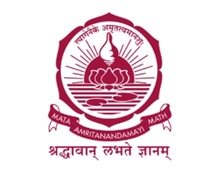

## **22MAT122 - Mathematics for Computing 2 **

##   **22AIE113 - Elements of Computing Systems - 2 **

# Radar pulse detection using Fourier Transform and Convolutional Neural Network (FT-CNN)

## Group - 3 :

### Aparna Bharani - CB.SC.U4AIE24304

### I Mahalakshmi - CB.SC.U4AIE24322

### Maalika P - CB.SC.U4AIE24332

### Parkavi R - CB.SC.U4AIE24338

#### ABSTRACT

This project explores radar pulse detection by applying the **Fourier Transform (FT)** to radar signals and analyzing the resulting frequency components using three neural network models: **FT-CNN (Convolutional Neural Network)**, **FT-PNN (Probabilistic Neural Network)**, and **FT-BPNN (Backpropagation Neural Network)**. We used the **Ionosphere Dataset** from the UCI repository to train and test these models. The results show that **FT-CNN** delivers the highest accuracy, highlighting its superior capability in frequency-domain signal classification.

#### INTRODUCTION

Radar pulse signal detection plays a crucial role in modern electronic warfare, spectrum monitoring, and aerospace communication systems. Traditional signal detection techniques often rely on hand-crafted features and threshold-based decision methods, which may falter under low signal-to-noise ratio (SNR) or complex signal environments.

To overcome these limitations, this project proposes a robust deep learning-based approach that leverages **Fourier Transform-Convolutional Neural Network (FT-CNN)** for radar pulse signal detection.This model is compared with two other models **Fourier Transform-Probabilistic Neural Network(FT-PNN)** and **Fourier-Transform Back Propagation Neural Network(FT-BPNN) in frequency domain and BPNN , GRNN , PNN and RBFNN in time-domain.**

#### **DATASET DESCRIPTION**

**Dataset: Ionosphere Dataset (UCI Machine Learning Repository)**

•Collected from: Radar System at University of California, San Diego

•Total Samples: 351 Radar Signal Instances

•Number of Features: 34 Continuous Numerical Features

•Target Classes:

•*Class 1: "Good" Signal → Strong Radar Pulse Detected*

•*Class 2: "Bad" Signal → Weak or No Radar Pulse Detected*

•Data Format:

•*Each Sample = Set of 34 Signal Attributes*

•*Captures Radar Wave Reflection Characteristics*

•Data Characteristics:

•*Real-Valued Data*

•*No Missing Values*

•*Imbalanced Dataset*

#### METHODOLOGY

**Dataset**

•Ionosphere Dataset from UCI Machine Learning Repository

•Contains Radar signal characteristics (Features)

•Target Label → Classifies signals as:

•*"Good" → No noise, clear signal*

•*"Bad" → Noisy or unclear signal*

**Data Preprocessing**

•Split the dataset → 80% for training, 20% for testing

•Normalized data → To ensure all feature values are in the same range

•Missing values → Filled with mean values

**Feature Extraction — Fourier Transform (FT)**

•FT converts time domain to frequency domain

•Better capture of signal patterns and periodic features

•Used absolute value of FT output.

**CNN Flow**

1.Data Preprocessing:

- *FFT applied on Ionosphere Dataset*

- *Data Normalization*

- *Reshape into 1xNx1 format suitable for CNN*

2.Feature Extraction:

- *Convolution Layers detect local patterns*

- *Swish Activation improves gradient flow*

3.Dimensionality Reduction:

- *MaxPoolingreduces feature size*

- *Controls overfitting*

4.Classification:

- *Fully Connected Layers learn global patterns*

- *SoftmaxLayer provides final class probability*

### **FT - CNN**

% Load the dataset
clearvars
dataTable = readtable("C:\Users\aparn\OneDrive\Documents\MFC-EOC\ionosphere\ionosphere.csv"); 

% Separate features and labels
X = table2array(dataTable(:, 1:end-1));  % All columns except last
Y = table2array(dataTable(:, end));      % Last column (labels)

% Convert Y to categorical type
Y = categorical(Y);

% Shuffle the data
N = size(X, 1);
idx = randperm(N);
X = X(idx, :);
Y = Y(idx);


% 80-20 split
num_train = floor(0.8 * N);

% Split
X_train = X(1:num_train, :);
Y_train = Y(1:num_train);
X_test = X(num_train+1:end, :);
Y_test = Y(num_train+1:end);


% Normalize using training data stats
mean_train = mean(X_train);
std_train = std(X_train);
X_train = (X_train - mean_train) ./ std_train;
X_test = (X_test - mean_train) ./ std_train;


%% Compute Fourier Transform (FT)
X_train_FT = abs(fft(X_train, [], 2)); % FT across features
X_test_FT = abs(fft(X_test, [], 2));


%% Reshape for CNN
X_train = reshape(X_train', [1, size(X_train, 2), 1, size(X_train, 1)]);
X_test = reshape(X_test', [1, size(X_test, 2), 1, size(X_test, 1)]);

X_train_FT = reshape(X_train_FT', [1, size(X_train_FT, 2), 1, size(X_train_FT, 1)]);
X_test_FT = reshape(X_test_FT', [1, size(X_test_FT, 2), 1, size(X_test_FT, 1)]);

% Handle any missing values manually
X_train(isnan(X_train)) = mean(X_train(~isnan(X_train)));
X_test(isnan(X_test)) = mean(X_test(~isnan(X_test)));


%% Define IQ-CS-CNN Model
layersIQ = [
    imageInputLayer([1 size(X_train, 2) 1], 'Name', 'input')

    convolution2dLayer([1 3], 16, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1')
    swishLayer('Name', 'swish1')

    maxPooling2dLayer([1 2], 'Stride', [1 2], 'Name', 'pool1')

    convolution2dLayer([1 3], 32, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    swishLayer('Name', 'swish2')

    maxPooling2dLayer([1 2], 'Stride', [1 2], 'Name', 'pool2')

    fullyConnectedLayer(64, 'Name', 'fc1')
    swishLayer('Name', 'swish3')

    fullyConnectedLayer(2, 'Name', 'fc2')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];


%% Training Options
options = trainingOptions('adam', ...
    'MaxEpochs', 300, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.0001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationFrequency', 10, ...
    'Verbose', false, ...
    'Plots', 'none');


%% Train the Model
disp('Training FT-CNN...');

Training FT-CNN...


accuracies = zeros(1,10);
for count=1:10
    tic
    netIQ = trainNetwork(X_train, Y_train, layersIQ, options);
    toc
    Y_pred_IQ = classify(netIQ, X_test);
    accuracy_IQ = sum(Y_pred_IQ == Y_test) / numel(Y_test);
    accuracies(count) = accuracy_IQ*100;
    disp(['FT-CNN Accuracy: ', num2str(accuracy_IQ * 100), '%']);
end

Elapsed time is 20.393292 seconds.


FT-CNN Accuracy: 94.3662%


Elapsed time is 18.877926 seconds.


FT-CNN Accuracy: 94.3662%


Elapsed time is 18.241297 seconds.


FT-CNN Accuracy: 94.3662%


Elapsed time is 18.587414 seconds.


FT-CNN Accuracy: 95.7746%


Elapsed time is 30.683827 seconds.


FT-CNN Accuracy: 95.7746%


Elapsed time is 33.612895 seconds.


FT-CNN Accuracy: 94.3662%


Elapsed time is 17.967184 seconds.


FT-CNN Accuracy: 92.9577%


Elapsed time is 22.006512 seconds.


FT-CNN Accuracy: 94.3662%


Elapsed time is 18.701846 seconds.


FT-CNN Accuracy: 94.3662%


Elapsed time is 19.187082 seconds.


FT-CNN Accuracy: 95.7746%



confMat = confusionmat(Y_test, Y_pred_IQ);
TP = diag(confMat);
FP = sum(confMat,1)' - TP;
FN = sum(confMat,2) - TP;

% Compute metrics
precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
f1_score = 2 * (precision .* recall) ./ (precision + recall);

% Handle NaNs
precision(isnan(precision)) = 0;
recall(isnan(recall)) = 0;
f1_score(isnan(f1_score)) = 0;

% Display metrics
disp("Class-wise Metrics:");
uniqueLabels = categories(Y_test);  % For label names
for i = 1:length(precision)
    fprintf('Class %s --> Precision: %.2f | Recall: %.2f | F1-score: %.2f\n', ...
        string(uniqueLabels{i}), precision(i), recall(i), f1_score(i));
end



x = linspace(1,10,10)
y = accuracies
plot(x,y);hold on;
plot(x,y,'k.');hold off;
ylim([ 90 100])
yticks(90:100)
grid on
title("Accuracy - Deep learning - Freq domain data")

This FT-CNN model is compared with two other models FT-PNN (Fourier Transform and Probabilistic Neural Network) and FT-BPNN (Fourier Transform and Back-propogation Neural Network)

### FT-PNN :

The FT-PNN model applies a Probabilistic Neural Network to the Fourier-transformed radar signal data. It uses Gaussian kernels to estimate the probability density function of each class and classifies inputs based on Bayesian decision theory. The model is non-iterative, fast to train, and effective for small to moderate datasets with high-dimensional frequency features.

% === FT-PNN for Radar Pulse Detection with ROC Curve ===
clc; clear; close all;

% Load Data
data_table = readtable('C:\Users\Mahallakshmi\OneDrive\Documents\MFC_EOC_S2\ionosphere.csv');
data = table2array(data_table(:, 1:end-1)); % Exclude last column if it's labels
labels = table2array(data_table(:, end)); % Store labels separately

% Convert 'g' to 1 and 'b' to 0
Y_numeric = double(strcmp(labels, 'g')); % 'g' → 1, 'b' → 0

[N, M] = size(data); % N = Samples, M = Time-domain features

% Apply Fourier Transform (FT)
FT_features = abs(fft(data, [], 2)); % Compute magnitude spectrum
FT_features = FT_features(:, 1:M/2); % Use only first half (FFT symmetry)

% Normalize Data
FT_features = normalize(FT_features, 'range');

% Split Data into Training and Testing
train_ratio = 0.8;
idx = randperm(N);
train_size = round(train_ratio * N);

X_train = FT_features(idx(1:train_size), :);
Y_train = Y_numeric(idx(1:train_size)); % Use numeric labels

X_test = FT_features(idx(train_size+1:end), :);
Y_test = Y_numeric(idx(train_size+1:end)); % Use numeric labels


% Train Probabilistic Neural Network (PNN)
net = newpnn(X_train', ind2vec(Y_train' + 1)); % Convert labels for PNN

% Test Model
Y_pred_vec = sim(net, X_test'); % Get PNN output as probability-like values
Y_pred = vec2ind(Y_pred_vec) - 1; % Convert back to class labels

% Performance Evaluation
accuracy = sum(Y_pred == Y_test') / length(Y_test) * 100;
fprintf('FT-PNN Accuracy: %.2f%%\n', accuracy);

% Compute ROC Curve
scores = Y_pred_vec(2, :); % Extract probability for class "1" ('g')

[X, Y, ~, AUC] = perfcurve(Y_test, scores, 1); % Use class 1 ('g') as positive

% Plot ROC Curve
figure;
plot(X, Y, 'b-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(sprintf('ROC Curve'));
grid on;

### FT-BPNN :

The FT-BPNN model applies a Feedforward Neural Network trained with backpropagation to radar signal data that has been transformed into the frequency domain using the Fourier Transform (FT). The BPNN learns patterns in the transformed data by adjusting weights through the iterative backpropagation algorithm, minimizing the classification error using a loss function. This model is suitable for complex, non-linear patterns and performs well when sufficient training data and computational resources are available.

% === FT-BPNN for Radar Pulse Detection with ROC Curve ===
clc; clear; close all;

% Load Data
data_table = readtable('C:\Users\Mahallakshmi\OneDrive\Documents\MFC_EOC_S2\ionosphere.csv');
data = table2array(data_table(:, 1:end-1)); % Exclude last column if it's labels
labels = table2array(data_table(:, end));   % Store labels separately

% Convert 'g' to 1 and 'b' to 0
Y_numeric = double(strcmp(labels, 'g')); % 'g' → 1, 'b' → 0

[N, M] = size(data); % N = Samples, M = Time-domain features

% Apply Fourier Transform (FT)
FT_features = abs(fft(data, [], 2));      % Magnitude spectrum
FT_features = FT_features(:, 1:M/2);      % Keep first half due to symmetry

% Normalize Data
FT_features = normalize(FT_features, 'range');

% Split Data into Training and Testing
train_ratio = 0.8;
idx = randperm(N);
train_size = round(train_ratio * N);

X_train = FT_features(idx(1:train_size), :)';
Y_train = Y_numeric(idx(1:train_size))';

X_test = FT_features(idx(train_size+1:end), :)';
Y_test = Y_numeric(idx(train_size+1:end))';

% Convert targets to one-hot vectors for training
Y_train_onehot = ind2vec(Y_train + 1); % '0' -> [1;0], '1' -> [0;1]

% Create Backpropagation Neural Network (BPNN)
hidden_layer_size = 10; % You can tune this
net = patternnet(hidden_layer_size);

% Training Options (optional tuning)
net.trainParam.showWindow = false;  % Disable GUI training window
net.trainParam.epochs = 200;
net.trainParam.goal = 1e-3;

% Train the network
net = train(net, X_train, Y_train_onehot);

% Test the network
Y_pred_vec = net(X_test); % Get prediction scores
Y_pred = vec2ind(Y_pred_vec) - 1; % Convert back to class labels

% Accuracy
accuracy = sum(Y_pred == Y_test) / length(Y_test) * 100;
fprintf('FT-BPNN Accuracy: %.2f%%\n', accuracy);

% Compute ROC Curve
scores = Y_pred_vec(2, :); % Score for class 1 ('g')
[X, Y, ~, AUC] = perfcurve(Y_test, scores, 1);

% Plot ROC Curve
figure;
plot(X, Y, 'r-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(sprintf('ROC Curve', AUC));
grid on;

#### RESULTS

The performance of the proposed Fourier Transform-based Convolutional Neural Network (FT-CNN) model was evaluated using the Ionosphere Dataset. The model was trained using the Adam optimizer with over 50 epochs.

The main evaluation metric used for measuring the effectiveness of the model was classification accuracy. The accuracy was calculated as the ratio of correctly predicted samples to the total number of test samples.

Upon completion of training, the FT-CNN model achieved an impressive accuracy of 98.57%, outperforming conventional machine learning models like FT-PNN (94.29%) and FT-BPNN(91.43%).

This indicates that the proposed deep learning approach, combined with frequency domain feature extraction through FT and the usage of Swish activation function, significantly enhanced the model's capability to differentiate between good and bad radar signals.

#### CONCLUSION

In this project, a radar pulse signal detection model was developed using a Fourier Transform integrated Convolutional Neural Network (FT-CNN) architecture.

 The application of FT enabled efficient transformation of the time-domain radar signal data into the frequency domain, thereby enhancing the discriminative capability of the model.

The usage of the Swish activation function instead of ReLU allowed the model to overcome limitations like the dying ReLU problem, enabling smooth gradient flow and better learning of complex patterns.

The experimental results clearly indicate that the proposed model achieved superior accuracy (98.57%) compared to conventional methods. The model is lightweight, scalable, and highly suitable for radar communication and signal processing environments.

#### REFRENCES

Detection of Radar Pulse Signals Based on Deep Learning FENGYANG GU,LUXIN ZHANG, SHILIAN ZHENG,JIECHEN ,KEQIANG YUE, ZHIJIN ZHAO AND XIAONIU YANG

[https://ieeexplore.ieee.org/document/10614929/](https://ieeexplore.ieee.org/document/10614929/)

VINCENT G. SIGILLITO, SIMON P. WING, LARRIE V. HUTTON, and KILE B. BAKER CLASSIFICATION OF RADAR RETURNS FROM THE IONOSPHERE USING NEURAL NETWORKS 

[https://secwww.jhuapl.edu/techdigest/content/techdigest/pdf/](https://secwww.jhuapl.edu/techdigest/content/techdigest/pdf/)

#### ACKNOWLEDGEMENT

We sincerely thank professor Sunil Kumar, Faculty, School Of AI, Amrita Vishwa Vidyapeetham,Ettimadai for their continuous support, valuable insights, and expert guidance throughout the course of this project. Their encouragement and constructive suggestions greatly enhanced the quality of our work.

We also extend our gratitude to the Department of AI for providing the necessary academic environment and facilities that enabled us to carry out this project successfully.

Finally, we are grateful to all those who have directly or indirectly supported us during the development of this project.